# Main Script

## Initialization

clear
close all
clc


## Model Parameters Loading

Model_Parameters;


## Controller Parameters Definition & Controller Tune

% Current Controller
Ri.wb = 200;                     % current bandwidth                         [rad/s]
Ri.mphi = 80 * pi/180;          % current phase margin                      [rad]


% Speed Controller
Rw.wb = 20;                     % speed bandwith                            [rad/s]
Rw.mphi = 65 * pi/180;         % speed phase margin                        [rad]


% Position Controller
Rt.wb = 40;                     % position bandwith                         [rad/s]
Rt.mphi = 90 * pi/180;


% Tune
Controller_Tune;

Ri, Rw, Rt

Ri = struct with fields:
      wb: 200
    mphi: 1.3963
     Tpi: 4.8824e-04
      Ki: 81.7912
      Kp: 0.0399


Rw = struct with fields:
      wb: 20
    mphi: 1.1345
     Tpi: 0.1518
      Ki: 0.2574
      Kp: 0.0391


Rt = struct with fields:
      wb: 40
    mphi: 1.5708
     Tpi: 0.0816
      Ki: 956.0322
      Kp: 78.0478


## Debug Plot of TFs

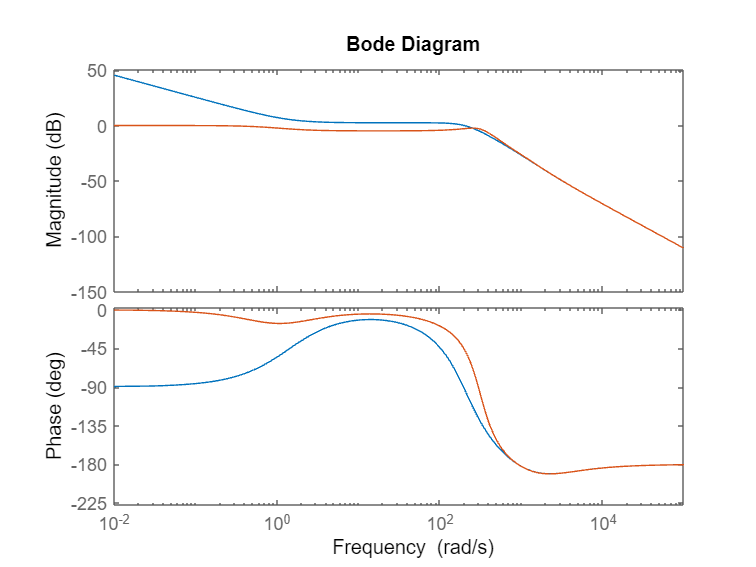

% Current Loop

figure(1);
bode(Li, Gi);

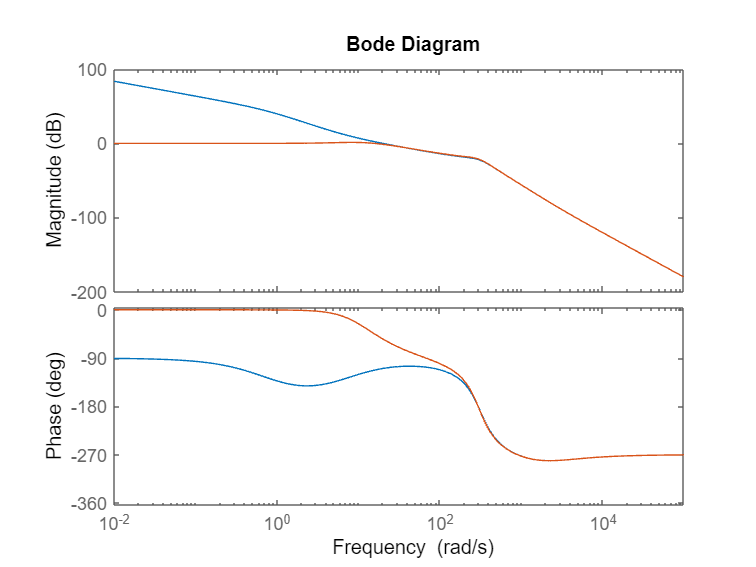



% Speed Loop

figure(2)
bode(Lw, Gw)

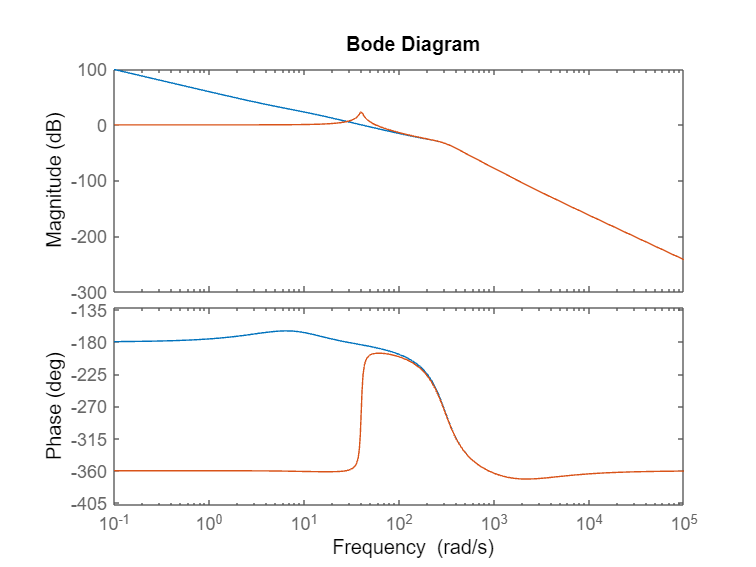



% Position Loop

figure(3)
bode(Lt, Gt)

## Observer Choice & Tune

% Simple Observer

Observer_Tune;


% Kalman Filter (4 states)

% Kalman_Tune;